Given the attached dataset, identify and validate a NFIR model of the processes.

------------------------------------------------------------------------------------------------------

**1. Process the data**

Load the dataset

ds = load('dati_nfir.mat')

ds = struct with fields:
    ingressi: [10081×5 double]
      uscita: [10081×1 double]


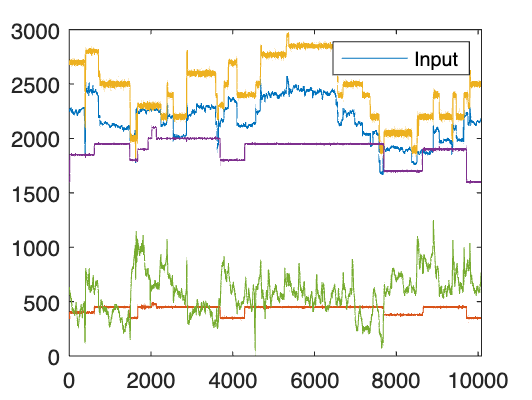

input_data = ds.ingressi; 
output_data = ds.uscita;
plot(input_data);
legend({'Input'})

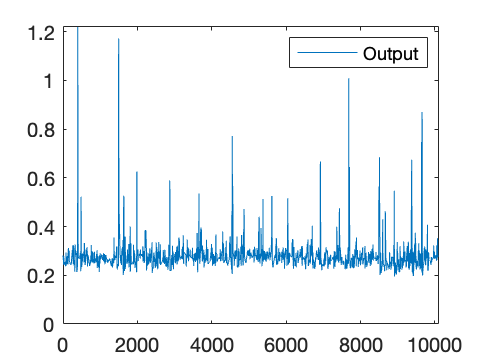


plot(output_data)
legend({'Output'})

We have the time series data.

**3 sigma-rule** is a simple and widely used heuristic for outlier detection. Basically any observations that fall outside of three standard deviations from the mean is considered an outlier.

sigma_output = (output_data - mean(output_data))/std(output_data);
sigma_input = (input_data -  mean(input_data))/std(input_data);
% std(): standard deviation
outliers_output = find(abs(sigma_output) >= 3)

outliers_output =    392
   393
   394
   395
   396
   397
   398
   399
   400
   401


outliers_input = find(abs(sigma_input) >= 3)


outliers_input =

  0×1 empty double column vector



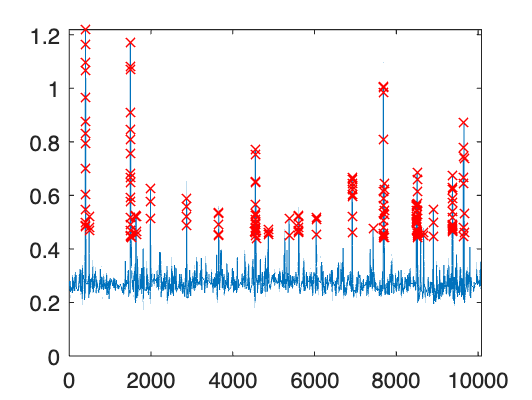

plot(output_data)
hold on
plot(outliers_output, output_data(outliers_output), 'rx')
hold off

**Z-score normalization**

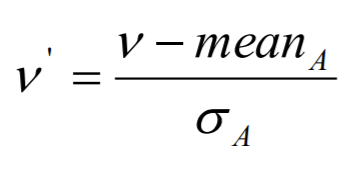               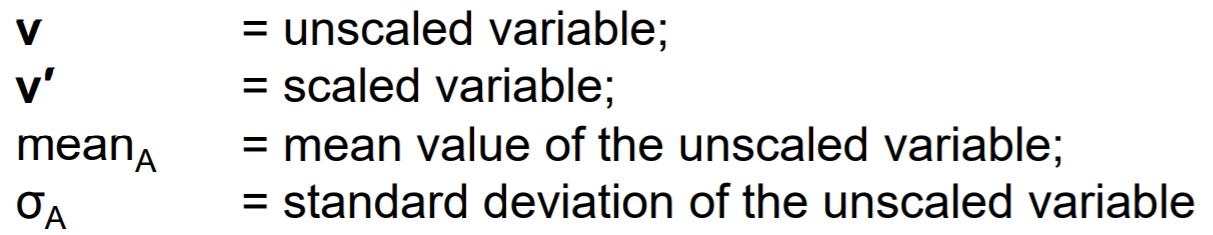

 **σ - standard deviation: **how far each value is from the mean

Normalize the data to get the same unit for all

input = zscore(input_data);
output = zscore(output_data);

io_normalization = zscore([input_data, output_data])

io_normalization =     0.4908   -2.0579    0.9312   -2.8639    0.1637    0.0501
    0.4755   -1.9960    0.8949   -2.8240    0.1797    0.0105
    0.4497   -2.0192    0.9015   -2.8194    0.1850   -0.0291
    0.4431   -2.1811    0.9121   -2.8169    0.1966   -0.0686
    0.4500   -2.3153    0.8704   -2.8061    0.2155   -0.1082
    0.4564   -2.1392    0.9167   -2.8186    0.2243   -0.1478
    0.4721   -2.1538    0.9024   -2.8117    0.1808   -0.1874
    0.4996   -2.2982    0.9190   -2.8221    0.1476   -0.2270
    0.4710   -1.5865    0.9061   -2.0884    0.1462   -0.2666
    0.4317   -0.7910    0.8379   -1.0598    0.1258   -0.3061


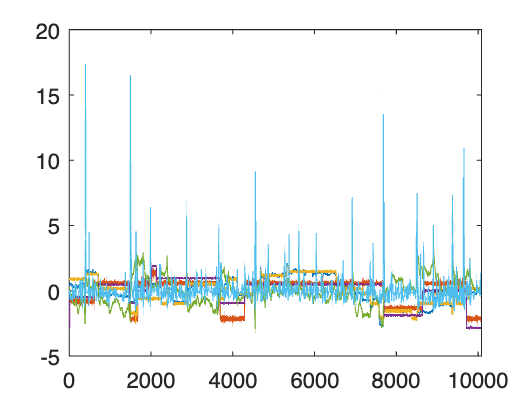

plot(io_normalization)


% The values used to accomplish the normalization
% must be computed on the whole data set and
% must not be changed in any further data manipulation

**Cross correlation **

Check the correlation between the identification and validation data sets.

disp('Input-Output identification')

Input-Output identification


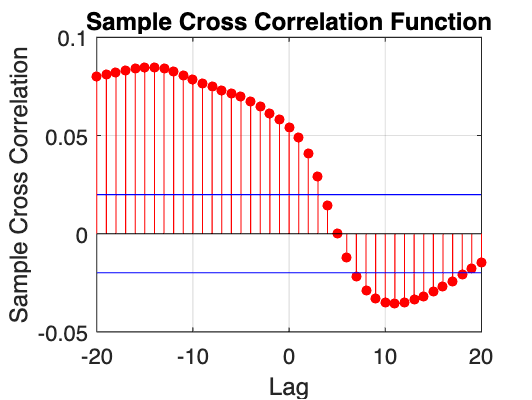

crosscorr(input(:,1),output)

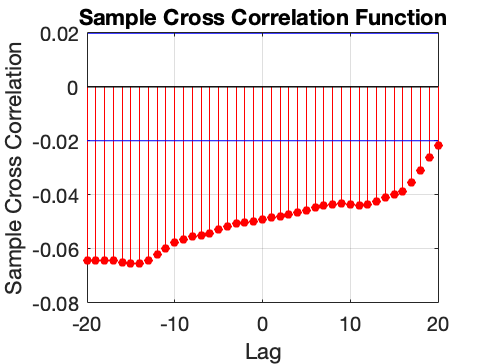

crosscorr(input(:,2),output)

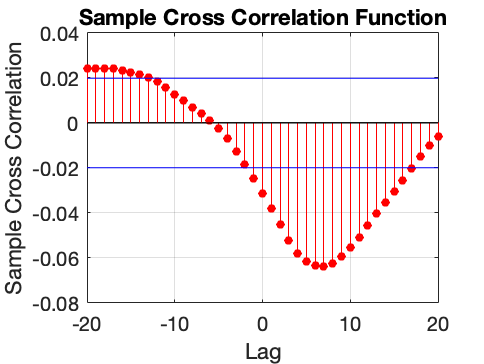

crosscorr(input(:,3),output)

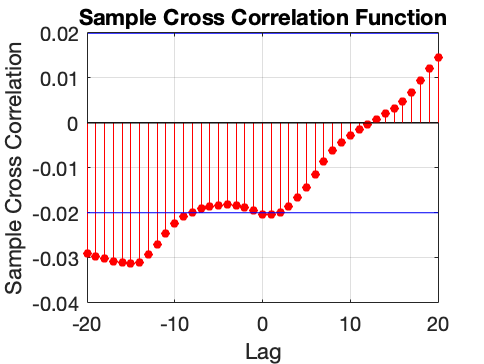

crosscorr(input(:,4),output)

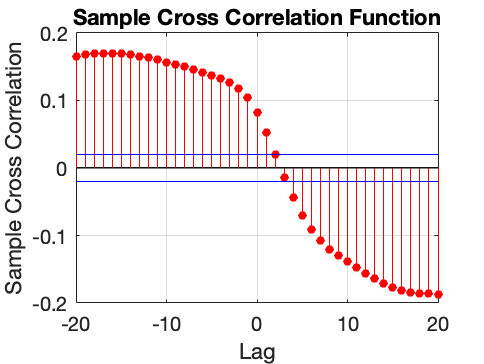

crosscorr(input(:,5),output)

There is no relevant correlation between the identification and validation, so there's no model for this. 

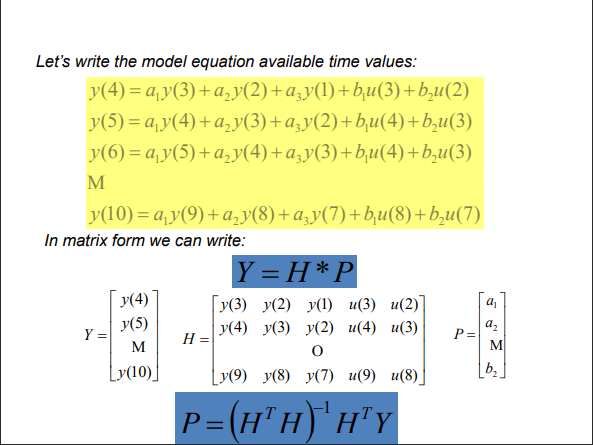

**NFIR**

NFIR: Nonlinear Finite Impulse Response

The NFIR model structure is given by the following equation:

disp('---------------------------')

---------------------------


disp('NFIR')

NFIR


disp('2nd order NFIR model')

2nd order NFIR model


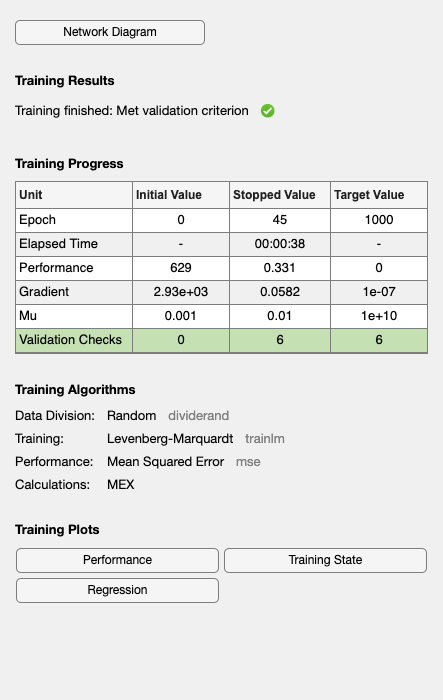

H_nfir=[input(10:10081, 5) input(7:10078, 5)];
y_nfir=output(10:10081)';
nn_nfir= newff(H_nfir',y_nfir,[20 20]);
[trained,TR3]=train(nn_nfir,H_nfir',y_nfir);

Performance

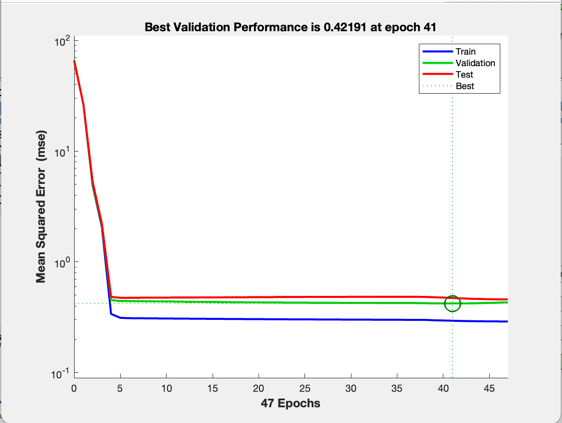

Training state

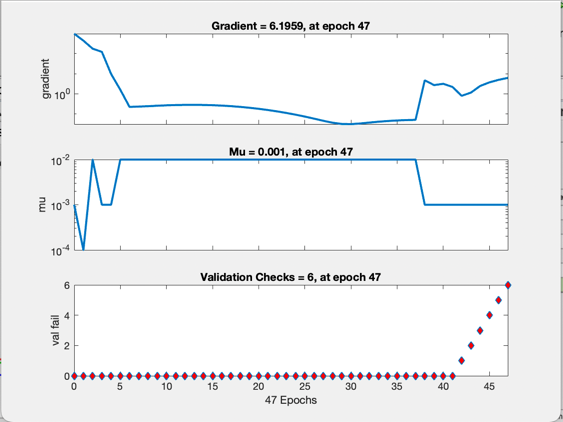

Regression

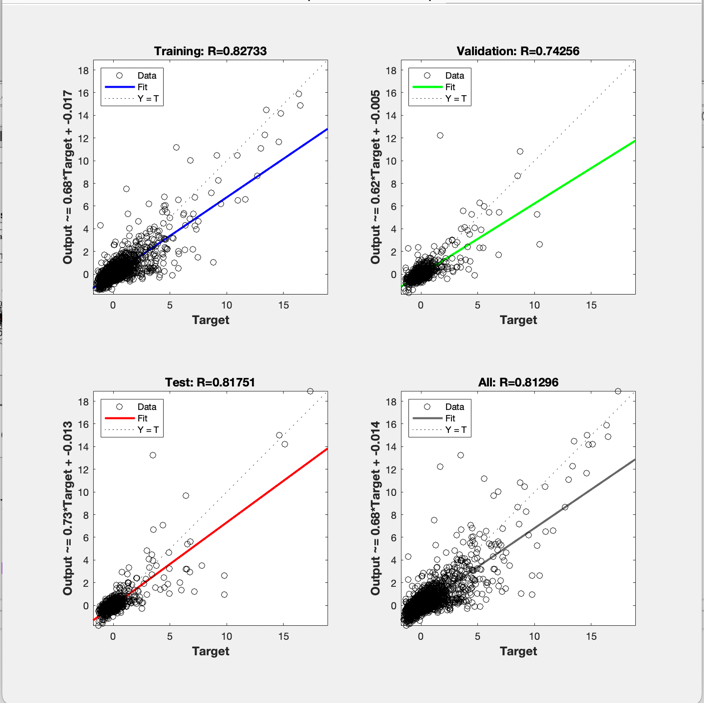

Get the residual and mean squared error:

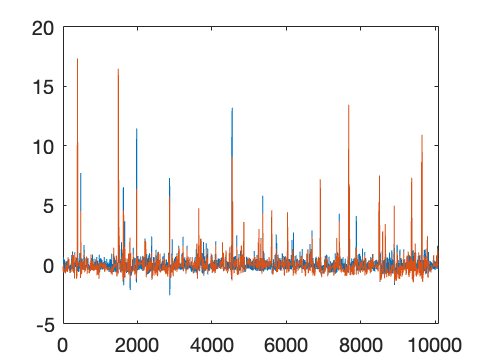

y_sim=sim(trained,H_nfir');
plot([y_sim' y_nfir'])

corrcoef(y_sim, y_nfir)

ans =     1.0000    0.8070
    0.8070    1.0000


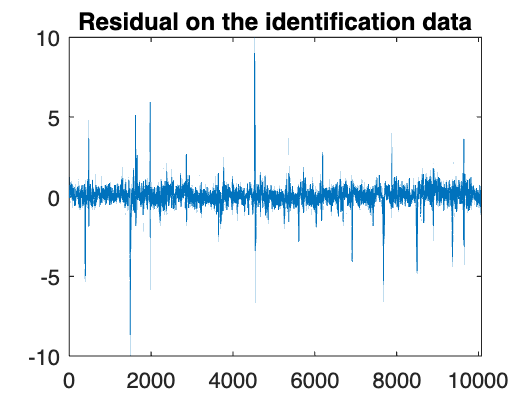

residual = y_sim - y_nfir;
plot(residual);
title("Residual on the identification data");

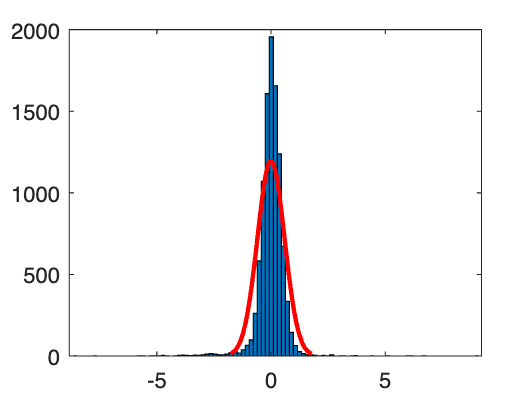

histfit(residual);

% mean squared error
mse = (immse(y_sim, y_nfir));
disp("Mean squared error: "+mse);

Mean squared error: 0.34913


The correlation coefficient is around 0.8 to 1 

the `Mean squared error: 0.34027`